s = tf('s');

J_xx = ureal('J_xx', 0.001630, 'Percentage', 5);
J_yy = ureal('J_yy', 0.002156, 'Percentage', 5);
J_zz = ureal('J_zz', 0.003281, 'Percentage', 5);

A = [0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1;
     0 0 0 0 0 0;
     0 0 0 0 0 0;
     0 0 0 0 0 0];

B = [0 0 0;
     0 0 0;
     0 0 0;
     1/J_xx 0 0;
     0 1/J_yy 0;
     0 0 1/J_zz];

C = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 1 0 0 0];

D = [0 0 0;
     0 0 0;
     0 0 0];

Q = ss(A, B, C, D);
Q.StateName = {'theta_x', 'theta_y', 'theta_z', 'omega_x', 'omega_y', 'omega_z'};
Q.InputName = 'M_d';
Q.OutputName = 'bar_theta';

% Define uncertain transfer functions for actuator dynamics
F_tc = ureal('F_tc', 0.033, 'Percentage', 15);
F_k = ureal('F_k', 1, 'Percentage', 20);
F_td = ureal('F_td', 0.0349, 'Percentage', 26);

F_i = F_k/(F_tc*s + 1);%exp(-F_td*s)*F_k/(F_tc*s + 1);

F = [F_i  0       0; 
     0              F_i   0;
     0              0               F_i];
F.u = 'u';
F.y = 'M';

d_add = sumblk('M_d = d + M',3);

% Connect all above blocks
P = connect(F.NominalValue, d_add, Q.NominalValue, {'u', 'd'}, {'bar_theta'})*exp(-F_td.NominalValue*s);

w_c = 2.5;

Kp = ss(w_c^2*eye(3,3));
Kp.u = 'e';
Kp.y = 'up';
Kd = ss(2*w_c*s*eye(3,3));
Kd.u = 'bar_theta';
Kd.y = 'ud';

err = sumblk('e = r - bar_theta', 3);
PD_add = sumblk('M_d = up - ud', 3);

L = connect(Kp,Kd,Q.NominalValue,err,PD_add, {'r'}, {'bar_theta'});
tf(L(1,1))


ans =
 
  From input "r(1)" to output "bar_theta(1)":
         3834
  -------------------
  s^2 + 3067 s + 3834
 
Continuous-time transfer function.


tf(L(2,2))


ans =
 
  From input "r(2)" to output "bar_theta(2)":
         2899
  -------------------
  s^2 + 2319 s + 2899
 
Continuous-time transfer function.


tf(L(3,3))


ans =
 
  From input "r(3)" to output "bar_theta(3)":
         1905
  -------------------
  s^2 + 1524 s + 1905
 
Continuous-time transfer function.


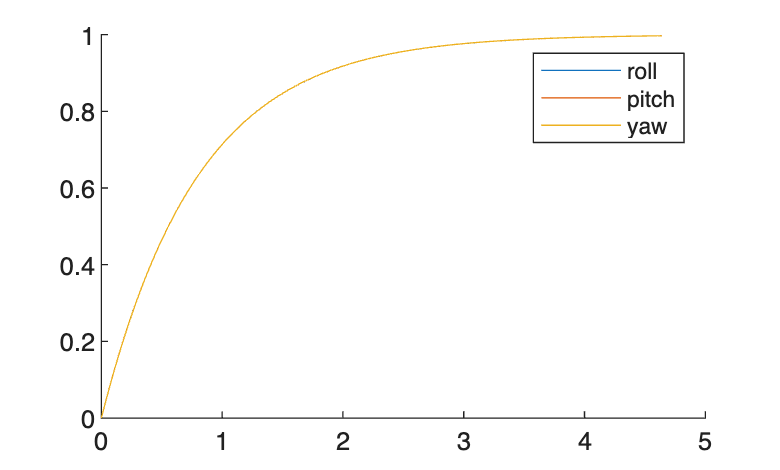


[y1,t1]=step(L(1,1));
[y2,t2]=step(L(2,2));
[y3,t3]=step(L(3,3));

figure, clf, hold on
plot(t1,y1);
plot(t2,y2);
plot(t3,y3);
legend("roll", "pitch","yaw")